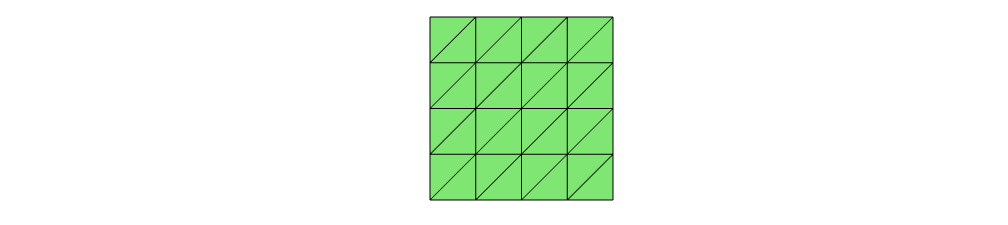

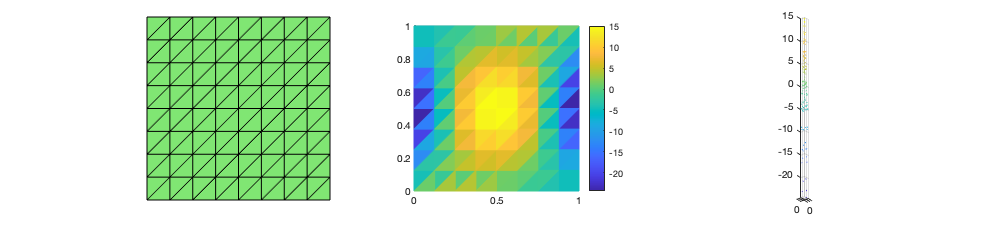

%% SQUARESTOKE Stokes equations on the unit square
%
%   SQUARESTOKE computes P2-P1 approximations of the Stokes equations in
%   the unit square on a sequence of meshes obtained by uniform refinement.
%   It plots the approximation error (pressue in L2 norm and velocity in H1
%   norm) vs the number of dof. Other types of FEM approximation can be
%   computed similarly.
% 
% See also StokesP2P1, collidingflow, squarePoisson 
%
% Copyright (C)  Long Chen. See COPYRIGHT.txt for details.

close all; 
clear variables;
%% Set up
maxIt = 4;
N = zeros(maxIt,1); 
h = zeros(maxIt,1);
erru = zeros(maxIt,1); 
errp = zeros(maxIt,1);

%% Generate initial mesh
[node,elem] = squaremesh([0 1 0 1], 0.25);
bdFlag = setboundary(node,elem,'Dirichlet');
showmesh(node, elem);

%% PDE and options
% pde = Stokesdata2;
pde = MyStokesData2;
% pde = Stokesdata3;

%% Finite Element Method        
for k = 1:maxIt
    % refine mesh
    [node,elem,bdFlag] = uniformrefine(node,elem,bdFlag);
    % solve the equation
%     [soln,eqn] = StokesP2P1(node,elem,bdFlag,pde);
%     [soln,eqn] = StokesP2P0(node,elem,bdFlag,pde);
%     [soln,eqn] = StokesisoP2P1(node,elem,bdFlag,pde);
%     [soln,eqn] = StokesisoP2P0(node,elem,bdFlag,pde);
    [soln,eqn] = JinJinStkoesCRP0(node,elem,bdFlag,pde);
%     [soln,eqn] = StokesP1bP1(node,elem,bdFlag,pde);
    uh = soln.u;
    ph = soln.p;
    N(k) = length(uh)+length(ph);
    h(k) = 1./(sqrt(size(node,1))-1);
    if N(k) < 2e3 % show solution for small size
        figure(1);  showresult(node,elem,ph);    
    end
    % compute error
    % uI = pde.exactu([node;
    % (node(eqn.edge(:,1),:)+node(eqn.edge(:,2),:))/2]); % 其他元
    uI = pde.exactu((node(eqn.edge(:,1),:)+node(eqn.edge(:,2),:))/2); % CRP0元
    erru(k) = sqrt((uh-uI(:))'*eqn.A*(uh-uI(:)));
    errp(k) = getL2error(node,elem,pde.exactp,ph);
end

注解：CRP0元应该用

```matlab

uI = pde.exactu((node(eqn.edge(:,1),:)+node(eqn.edge(:,2),:))/2); % CRP0元

```

因为求解的是所有边的中点

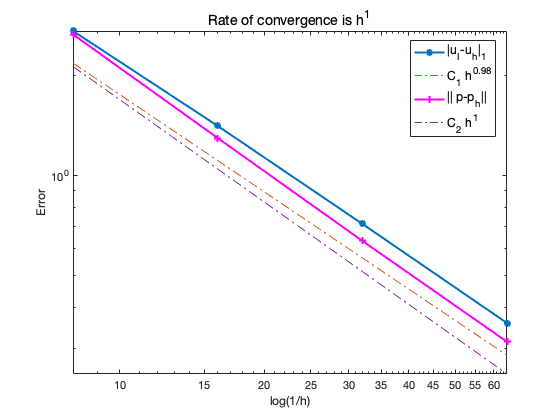


%% Plot convergence rates
figure(2);
showrateh2(h,erru,1,'-*','|u_I-u_h|_1',...
           h,errp,1,'m-+','|| p-p_h||');


fprintf('\n');
disp('Table: Error')

Table: Error


colname = {'#Dof','h','|u_I-u_h|_1','||p-p_h||'};
disptable(colname,N,[],h,'%0.3e',erru,'%0.5e',errp,'%0.5e');

 #Dof       h       |u_I-u_h|_1    ||p-p_h||   

  544   1.250e-01   2.73205e+00   2.66754e+00
 2112   6.250e-02   1.41193e+00   1.29770e+00
 8320   3.125e-02   7.14198e-01   6.34454e-01
33024   1.562e-02   3.58294e-01   3.14474e-01



注解：上述结果没有P2P1元效果好

% figure;
% set(gcf,'Units','normal'); 
% set(gcf,'Position',[0.25,0.25,0.55,0.4]);